clear
clc
close all

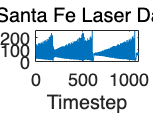

% data_train = readtable("lasertrain.dat");
% data_train(:,1:3) = [];
% data_train = table2array(data_train)';
% 
% data_test = readtable("laserpred.dat");
% data_test(:,1:3) = [];
% data_test = table2array(data_test)';
% 
% data = cat(2, data_train, data_test);
% 
% figure
% plot(data)
load("lasertrain.dat");
load("laserpred.dat");

data = [lasertrain.',laserpred.'];


figure
plot(data)
xlabel("Timestep")
title("Santa Fe Laser Data")

numTimeStepsTrain = 1000;

dataTrain = data(1:numTimeStepsTrain);
dataTest = data(numTimeStepsTrain+1:end);

## Standardize Data

For a better fit and to prevent the training from diverging, standardize the training data to have zero mean and unit variance. At prediction time, you must standardize the test data using the same parameters as the training data.

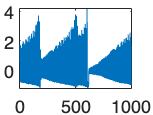

mu = mean(dataTrain);
sig = std(dataTrain);

dataTrainStandardized = (dataTrain - mu) / sig;
plot(dataTrainStandardized)

## Forecast Future Time Steps

To forecast the values of multiple time steps in the future, use the `predictAndUpdateState` function to predict time steps one at a time and update the network state at each prediction. For each prediction, use the previous prediction as input to the function.

Standardize the test data using the same parameters as the training data.

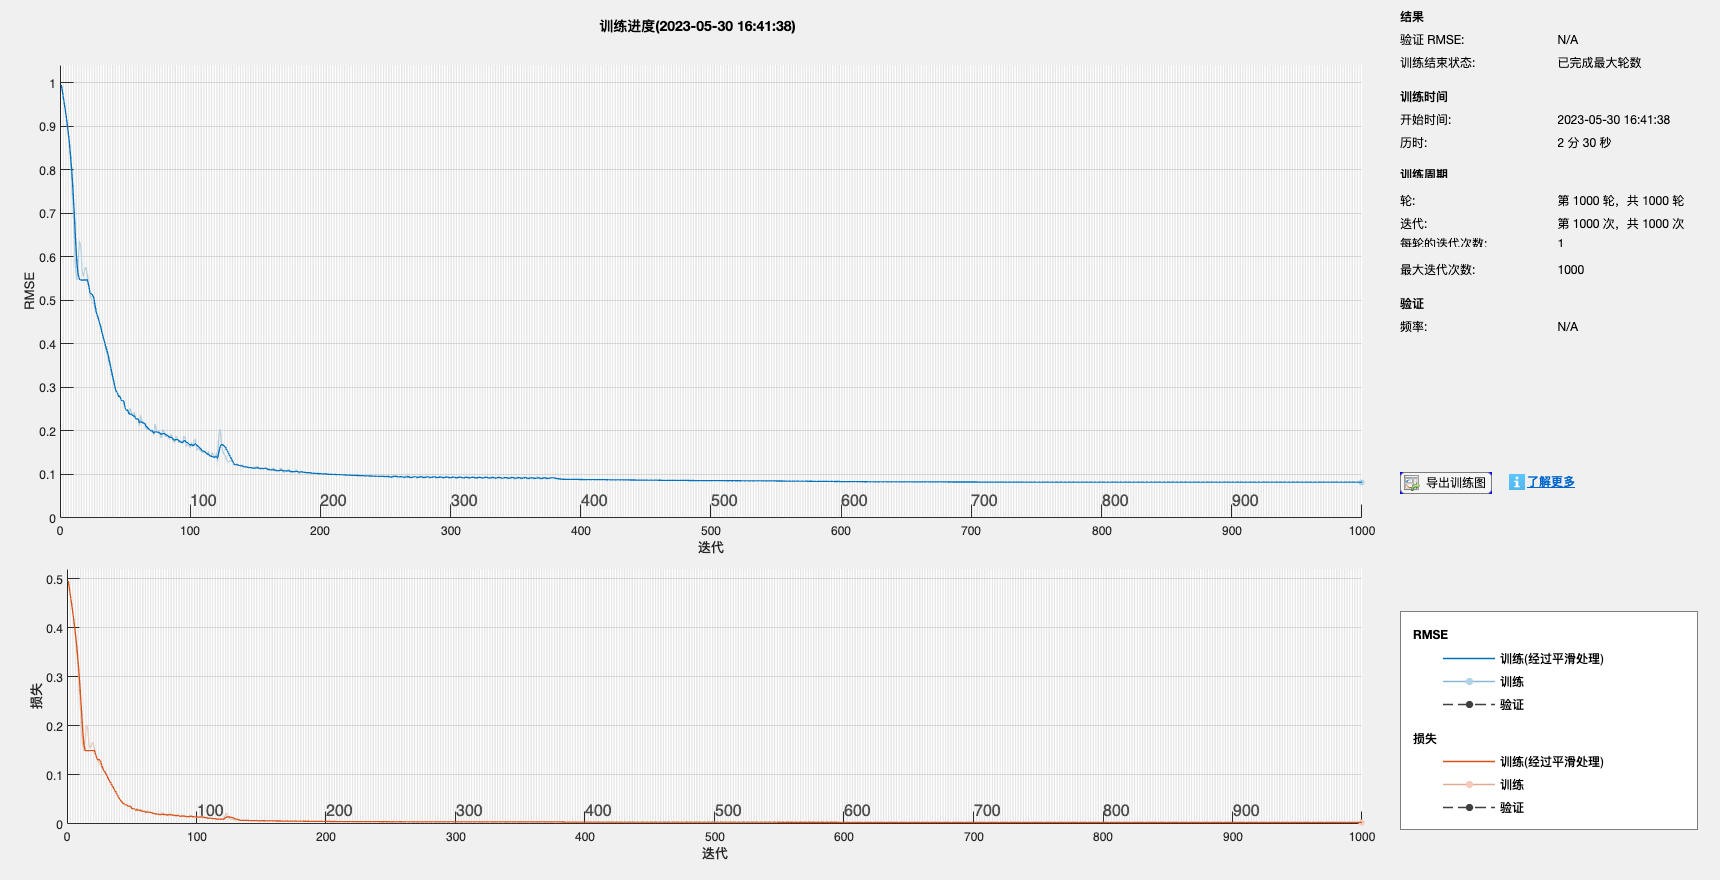

XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);
numFeatures = 1;
numResponses = 1;
numHiddenUnits = 50;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];
options = trainingOptions('adam', ...
    'MaxEpochs',1000, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');
net = trainNetwork(XTrain,YTrain,layers,options);

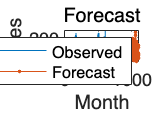


dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);

net = predictAndUpdateState(net,XTrain);
[net,YPred] = predictAndUpdateState(net,YTrain(end));

numTimeStepsTest = numel(XTest);
for i = 2:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1),'ExecutionEnvironment','cpu');
end

YPred = sig*YPred + mu;
YTest = dataTest(2:end);
rmse = sqrt(mean((YPred-YTest).^2));

figure
plot(dataTrain(1:end-1))
hold on
idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest);
plot(idx,[data(numTimeStepsTrain) YPred],'.-')
hold off
xlabel("Month")
ylabel("Cases")
title("Forecast")
legend(["Observed" "Forecast"])

Compare the forecasted values with the test data.

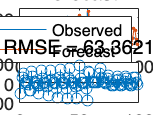

figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Forecast"])
ylabel("Cases")
title("Forecast")

subplot(2,1,2)
stem(YPred - YTest)
ylabel("Error")
title("RMSE = " + rmse)

## Update Network State with Observed Values

If you have access to the actual values of time steps between predictions, then you can update the network state with the observed values instead of the predicted values.

First, initialize the network state. To make predictions on a new sequence, reset the network state using `resetState`. Resetting the network state prevents previous predictions from affecting the predictions on the new data. Reset the network state, and then initialize the network state by predicting on the training data.

net = resetState(net);
net = predictAndUpdateState(net,XTrain);
YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end
YPred = sig*YPred + mu;
rmse = sqrt(mean((YPred-YTest).^2))

rmse = 11.3149

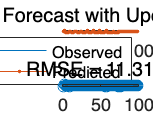

figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Predicted"])
ylabel("Cases")
title("Forecast with Updates")

subplot(2,1,2)
stem(YPred - YTest)
ylabel("Error")
title("RMSE = " + rmse)